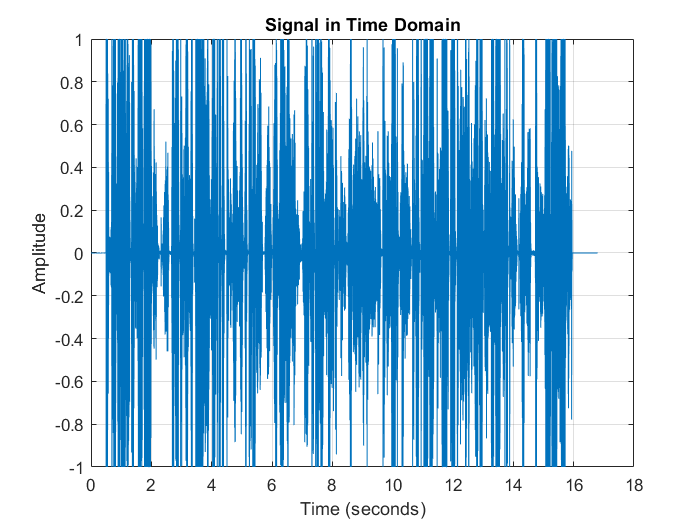

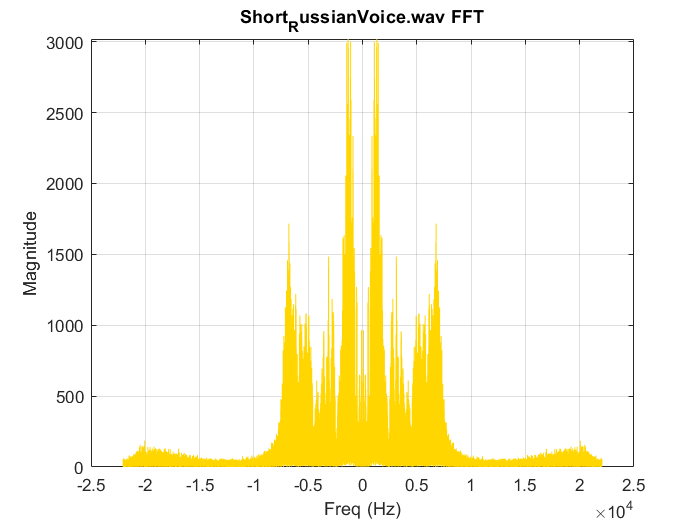

sampling frequency for all audios = 44100 Hz


clear; clc; close all;

% Initialize progress bar with previous style and new green bar shape
h = waitbar(0, 'Starting audio processing...', 'Name', 'Communication System Progress');
progress = 0; %#ok<*NASGU> 

% Collect user inputs at the beginning with friendly dropdowns
channel_options = {'Short_BBCArabic2', 'Short_FM9090', 'Short_QuranPalestine', 'Short_RussianVoice', 'Short_SkyNewsArabia'};
[selection, ok] = listdlg('PromptString', 'Select a channel:', ...
    'SelectionMode', 'single', ...
    'ListString', channel_options, ...
    'Name', 'Channel Selection');
if ~ok || isempty(selection)
    error('No channel selected. Please try again.');
end
choose_channel = selection;

test_options = {'Normal operation', 'Remove RF Filter', '0.1kHz Offset', '1kHz Offset'};
[test_selection, ok] = listdlg('PromptString', 'Select a test mode:', ...
    'SelectionMode', 'single', ...
    'ListString', test_options, ...
    'Name', 'Test Mode Selection');
if ~ok || isempty(test_selection)
    error('No test mode selected. Please try again.');
end
test = test_selection - 1;

% Update progress bar
progress = 0.02;
waitbar(progress, h, 'User inputs received...');

% Specifying the filenames of the audio files
transmitter_Audios = ["Short_BBCArabic2.wav", "Short_FM9090.wav", "Short_QuranPalestine.wav", "Short_RussianVoice.wav", "Short_SkyNewsArabia.wav"];

% Initialize variables
max_audio_length = 0;
band_widths = cell(1, length(transmitter_Audios));
BW_Of_chosen_Signal = 0;
BW_Of_last_Signal = 0;
current_sum = 0;
max_sum = 0;
FDM_Signal = 0;
RF_width = 0;
RF_Filter = 0;
IF = 25000;

% Update progress bar
progress = 0.05;
waitbar(progress, h, 'Obtaining maximum audio length...');

% Obtaining maximum length
for i = 1:length(transmitter_Audios)
    audio_signal = audioread(transmitter_Audios{i});
    audio_length = size(audio_signal, 1);
    if audio_length > max_audio_length
        max_audio_length = audio_length;
    end
    step_progress = 0.05/length(transmitter_Audios);
    progress = progress + step_progress;
    waitbar(progress, h, ['Checking audio length: ' transmitter_Audios{i}]);
end

% Update progress bar
progress = 0.1;
waitbar(progress, h, 'Padding and converting audios to mono...');

% Padding and convert Audios to Mono
for i = 1:length(transmitter_Audios)
    [audio_signal, Fs] = audioread(transmitter_Audios{i});
    audio_signal = sum(audio_signal, 2) / size(audio_signal, 2);
    audio_signal(end + max_audio_length - length(audio_signal)) = 0;
    audiowrite(transmitter_Audios{i}, audio_signal, Fs);
    step_progress = 0.05/length(transmitter_Audios);
    progress = progress + step_progress;
    waitbar(progress, h, ['Processing audio: ' transmitter_Audios{i}]);
end

% Update progress bar
progress = 0.15;
waitbar(progress, h, 'Analyzing FFT of selected audio...');

% FFT Of Desired Audio
for i = 1:length(transmitter_Audios)
    [audio_signal, Fs] = audioread(transmitter_Audios(i));
    if i == choose_channel
        nSamples = length(audio_signal);
        t = (0:nSamples-1) / Fs;
        figure;
        plot(t, audio_signal);
        xlabel('Time (seconds)');
        ylabel('Amplitude');
        title('Signal in Time Domain');
        ylim([-max(abs(audio_signal)) max(abs(audio_signal))]);
        grid on;
        figure;
        AUDIO_SIGNAL = fftshift(fft(audio_signal, length(audio_signal)));
        Frequency_vector = (-length(AUDIO_SIGNAL)/2 : length(AUDIO_SIGNAL)/2 - 1)';
        F = Frequency_vector*Fs/length(AUDIO_SIGNAL);
        plot(F, abs(AUDIO_SIGNAL), 'Color', [1, 0.84, 0]);
        title(transmitter_Audios(choose_channel) + " FFT");
        xlabel("Freq (Hz)");
        ylabel("Magnitude");
        ylim([0 max(abs(AUDIO_SIGNAL))]);
        grid on;
        disp("sampling frequency for all audios = " + Fs + " Hz");
    end
    step_progress = 0.05/length(transmitter_Audios);
    progress = progress + step_progress;
    waitbar(progress, h, ['Analyzing FFT: ' transmitter_Audios{i}]);
end

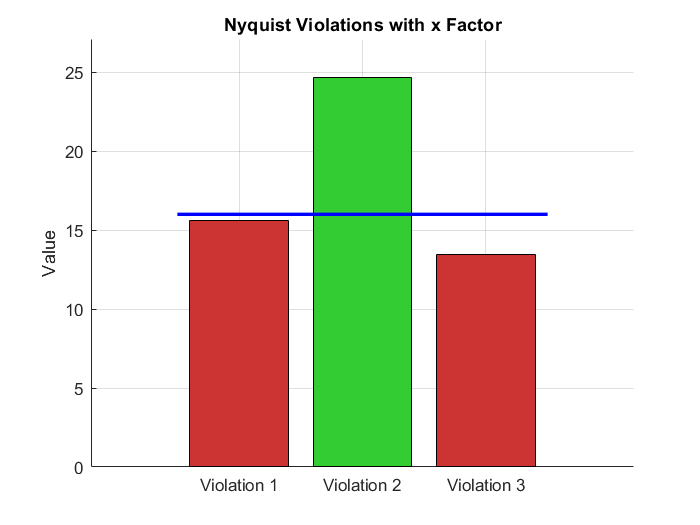


% Update progress bar
progress = 0.25;
waitbar(progress, h, 'Calculating bandwidths...');

% Calculate bandwidths
bandwidth_data = cell(length(transmitter_Audios), 3);
for i = 1:length(transmitter_Audios)
    [audio_signal, Fs] = audioread(transmitter_Audios(i));
    AUDIO_SIGNAL = fftshift(fft(audio_signal, length(audio_signal)));
    Frequency_vector = (-length(AUDIO_SIGNAL)/2 : length(AUDIO_SIGNAL)/2 - 1)';
    F = Frequency_vector*Fs/length(AUDIO_SIGNAL);
    N = length(AUDIO_SIGNAL);
    [pks, freqs] = findpeaks(abs(AUDIO_SIGNAL(1:N/2)), F(1:N/2), 'MinPeakHeight', 0.001*max(abs(AUDIO_SIGNAL(1:N/2))));
    full_bandwidth = max(freqs) - min(freqs);
    effective_bandwidth = obw(audio_signal, Fs);
    bandwidth = effective_bandwidth;
    % Display full length in Hz without scientific notation
    bandwidth_data{i, 1} = char(transmitter_Audios(i));
    bandwidth_data{i, 2} = num2str(full_bandwidth, '%.0f'); % Full length, no decimal, no scientific notation
    bandwidth_data{i, 3} = num2str(effective_bandwidth, '%.0f'); % Full length, no decimal, no scientific notation
    band_widths{i} = bandwidth;
    if i == choose_channel
        BW_Of_chosen_Signal = bandwidth;
    end
    if i == length(transmitter_Audios)
        BW_Of_last_Signal = bandwidth;
    end
    step_progress = 0.05/length(transmitter_Audios);
    progress = progress + step_progress;
    waitbar(progress, h, ['Calculating bandwidth: ' transmitter_Audios{i}]);
end

% Create bandwidth comparator table and keep it open
bandwidth_fig = figure('Name', 'Bandwidth Comparison Table');
t = uitable('Data', bandwidth_data, ...
    'ColumnName', {'Audio File', 'Full Bandwidth (hz)', 'Effective Bandwidth (hz)'}, ...
    'RowName', [], ...
    'Units', 'normalized', ...
    'Position', [0.1, 0.1, 0.8, 0.8]);
set(t, 'ColumnWidth', {150, 150, 150});

% Update progress bar
progress = 0.3;
waitbar(progress, h, 'Calculating frequency range...');

% Calculate available frequency range
for i = choose_channel-1:choose_channel
    if choose_channel == 1
        max_sum = band_widths{choose_channel} + band_widths{choose_channel+1};
    elseif choose_channel == 5
        max_sum = band_widths{choose_channel} + band_widths{choose_channel-1};
    else
        current_sum = band_widths{i} + band_widths{i+1};
        if current_sum > max_sum
            max_sum = current_sum;
        end
    end
end
k0 = BW_Of_chosen_Signal + (50000 - max_sum);
k1 = IF;

% Update progress bar
progress = 0.35;
waitbar(progress, h, 'Preparing for modulation...');

% Modulating
[audio_signal, Fs] = audioread(transmitter_Audios(choose_channel));
fo = 100000;
n = (choose_channel-1);
delta_f = 50000;
fn_chosen = fo + n*delta_f;

% Update progress bar
progress = 0.4;
waitbar(progress, h, 'Checking Nyquist criteria...');

% Automated Nyquist criteria
fmax1 = fo + (length(transmitter_Audios) - 1) * delta_f + k0;
fmax2 = 2*fn_chosen + IF + BW_Of_chosen_Signal;
violation_1 = (2/Fs)*(fmax1 + 1000);
violation_2 = (2/Fs)*(fmax2);
violation_3 = (1/Fs)*(fmax2 + IF + k1 + 1000);
if violation_1 >= violation_2
    x = violation_1;
elseif violation_1 >= violation_3
    x = violation_1;
else
    x = violation_3;
end
x = ceil(x);

% Create violations bar chart with x line
figure;
violations = [violation_1, violation_2, violation_3];

% Define colors based on condition
bar_colors = [0.8 0.2 0.2; 0.8 0.2 0.2; 0.8 0.2 0.2]; % Default all red
if x < violation_2
    bar_colors(2,:) = [0.2 0.8 0.2]; % Make Violation 2 green
end

% Plot bars one by one with appropriate colors
hold on;
for i = 1:3
    bar(i, violations(i), 'FaceColor', bar_colors(i,:));
end

plot([0.5 3.5], [x x], 'b-', 'LineWidth', 2); % x line
set(gca, 'XTick', 1:3, 'XTickLabel', {'Violation 1', 'Violation 2', 'Violation 3'});
ylabel('Value');
title('Nyquist Violations with x Factor');
ylim([0 max([violations x])*1.1]);
grid on;
hold off;

disp("violation_1 = " + num2str(violation_1));

violation_1 = 15.596


disp("violation_2 = " + num2str(violation_2));

violation_2 = 24.6384


disp("violation_3 = " + num2str(violation_3));

violation_3 = 13.4757


disp("x = " + num2str(x));

x = 16


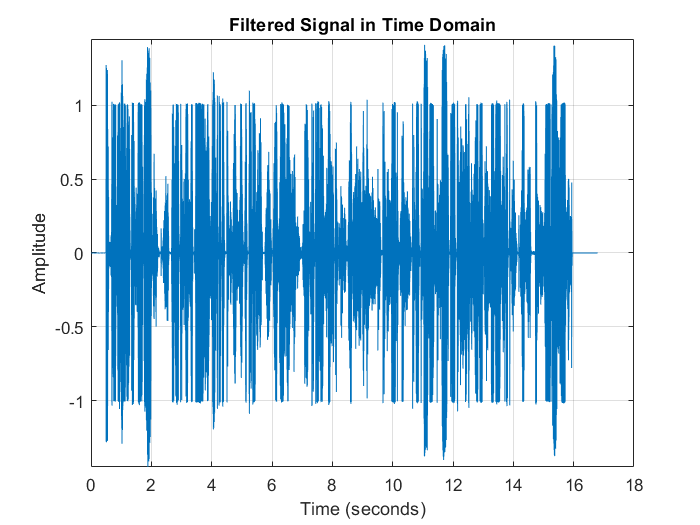

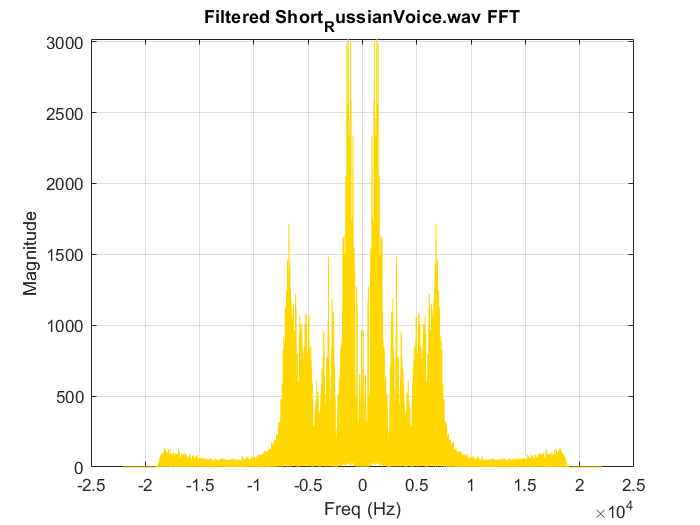

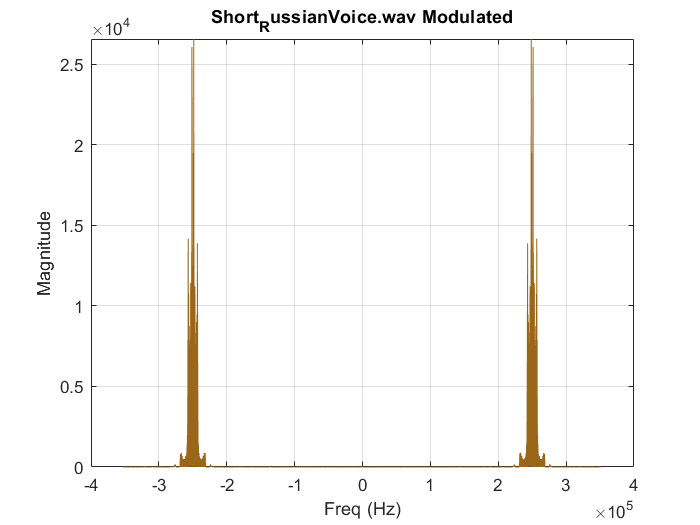

bandwidth of Short_RussianVoice.wav Modulated = 36552.7813 Hz



% Update progress bar
progress = 0.45;
waitbar(progress, h, 'Generating FDM signal...');

% FDM Signal Generation
for i = 1:length(transmitter_Audios)
    [audio_signal, Fs] = audioread(transmitter_Audios(i));
    F_pass = band_widths{i};
    F_stop = F_pass + 1000;
    A_stop = 60;
    A_pass = 1;
    Low_Pass_Filter = fdesign.lowpass(F_pass, F_stop, A_pass, A_stop, Fs);
    Low_Pass_Filter = design(Low_Pass_Filter, 'kaiserwin');
    [b, a] = tf(Low_Pass_Filter);
    audio_signal = filtfilt(b, a, audio_signal);
    if i == choose_channel
        nSamples = length(audio_signal);
        t = (0:nSamples-1) / Fs;
        figure;
        plot(t, audio_signal);
        xlabel('Time (seconds)');
        ylabel('Amplitude');
        title('Filtered Signal in Time Domain');
        ylim([-max(abs(audio_signal)) max(abs(audio_signal))]);
        grid on;
        figure;
        AUDIO_SIGNAL = fftshift(fft(audio_signal, length(audio_signal)));
        Frequency_vector = (-length(AUDIO_SIGNAL)/2 : length(AUDIO_SIGNAL)/2 - 1)';
        F = Frequency_vector*Fs/length(AUDIO_SIGNAL);
        plot(F, abs(AUDIO_SIGNAL), 'Color', [1, 0.84, 0]);
        title("Filtered " + transmitter_Audios(choose_channel) + " FFT");
        xlabel("Freq (Hz)");
        ylabel("Magnitude");
        ylim([0 max(abs(AUDIO_SIGNAL))]);
        grid on;
    end
    audio_signal = interp(audio_signal, x);
    waitbar(progress + 0.01, h, ['Interpolating signal: ' transmitter_Audios{i}]);
    fo = 100000;
    n = (i-1);
    delta_f = 50000;
    fn = fo + n*delta_f;
    audio_length = (1:1:length(audio_signal))';
    carrier_signal = cos(2*pi*fn*audio_length*(1/(x*Fs)));
    modulated_signal = carrier_signal.*audio_signal;
    MODULATED_SIGNAL = fftshift(fft(modulated_signal));
    Frequency_vector = (-length(MODULATED_SIGNAL)/2:1:length(MODULATED_SIGNAL)/2-1)';
    if i == choose_channel
        figure;
        plot(Frequency_vector*(x*Fs)/length(MODULATED_SIGNAL), abs(MODULATED_SIGNAL), 'Color', [0.6, 0.4, 0.1]);
        title(transmitter_Audios(choose_channel) + " Modulated");
        xlabel("Freq (Hz)");
        ylabel("Magnitude");
        ylim([0 max(abs(MODULATED_SIGNAL))]);
        grid on;
        bandwidth2 = 2 * BW_Of_chosen_Signal;
        disp("bandwidth of " + transmitter_Audios(choose_channel) + " Modulated = " + bandwidth2 + " Hz");
    end
    FDM_Signal = FDM_Signal + modulated_signal;
    step_progress = 0.1/length(transmitter_Audios);
    progress = progress + step_progress;
    waitbar(progress, h, ['Processing FDM for: ' transmitter_Audios{i}]);
end

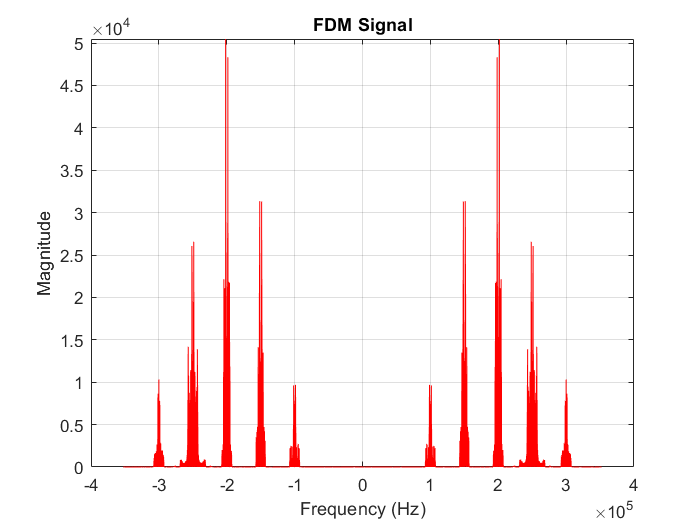


% Update progress bar
progress = 0.55;
waitbar(progress, h, 'Plotting FDM signal...');

figure;
FDM_SIGNAL = fftshift(fft(FDM_Signal));
Frequency_vector = (-length(FDM_SIGNAL)/2:length(FDM_SIGNAL)/2-1)';
plot(Frequency_vector*(x*Fs)/length(FDM_SIGNAL), abs(FDM_SIGNAL), 'r');
title("FDM Signal");
xlabel("Frequency (Hz)");
ylabel("Magnitude");
ylim([0 max(abs(FDM_SIGNAL))]);
grid on;


% Update progress bar
progress = 0.6;
waitbar(progress, h, 'Setting up RF stage...');

k_RF = k0 - 100;
disp("k_RF = " + num2str(k_RF) + " Hz");

k_RF = 42791.0994 Hz


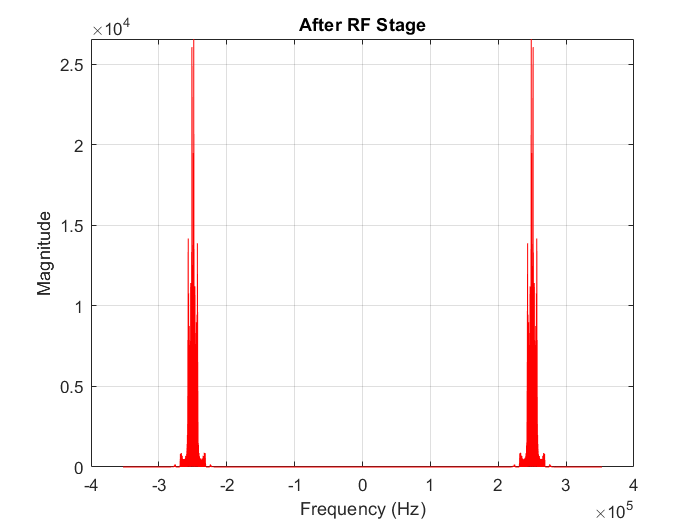


% Update progress bar
progress = 0.7;
waitbar(progress, h, 'RF filtering...');

if test ~= 1
    A_stop1 = 60;
    F_pass1 = fn_chosen - 0.5*(k_RF + BW_Of_chosen_Signal);
    F_pass2 = fn_chosen + 0.5*(k_RF + BW_Of_chosen_Signal);
    F_stop1 = fn_chosen - k_RF;
    F_stop2 = fn_chosen + k_RF;
    A_stop2 = 60;
    A_pass = 1;
    RF_Filter = fdesign.bandpass(F_stop1, F_pass1, F_pass2, F_stop2, A_stop1, A_pass, A_stop2, (x*Fs));
    RF_Filter = design(RF_Filter, 'kaiserwin');
    [b, a] = tf(RF_Filter);
    RF_Signal = filtfilt(b, a, FDM_Signal);
    figure;
    RF_SIGNAL = fftshift(fft(RF_Signal));
    Frequency_vector = (-length(RF_SIGNAL)/2:1:length(RF_SIGNAL)/2-1)';
    plot(Frequency_vector*(x*Fs)/length(RF_SIGNAL), abs(RF_SIGNAL), 'r');
    title("After RF Stage");
    xlabel("Frequency (Hz)");
    ylabel("Magnitude");
    ylim([0 max(abs(RF_SIGNAL))]);
    grid on;
end

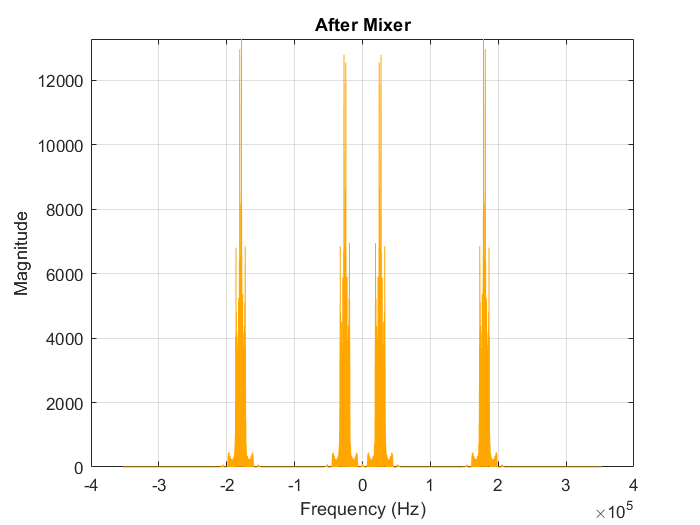


% Update progress bar
progress = 0.75;
waitbar(progress, h, 'Mixing signals...');

fn = (choose_channel-1)*50000+100000;
fLo = fn + IF;
if test == 1
    RF_Signal = FDM_Signal;
elseif test == 2
    fLo = fLo + 100;
elseif test == 3
    fLo = fLo + 1000;
end
audio_length = (1:1:length(RF_Signal))';
carrier_signal = cos(2*pi*fLo*audio_length*(1/(x*Fs)));
Mixer_Output_Signal = RF_Signal.*carrier_signal;
figure;
MIXER_OUTPUT_SIGNAL = fftshift(fft(Mixer_Output_Signal));
Frequency_vector = (-length(MIXER_OUTPUT_SIGNAL)/2:1:length(MIXER_OUTPUT_SIGNAL)/2-1)';
plot(Frequency_vector*(x*Fs)/length(MIXER_OUTPUT_SIGNAL), abs(MIXER_OUTPUT_SIGNAL), 'Color', [1, 0.65, 0]);
title("After Mixer");
xlabel("Frequency (Hz)");
ylabel("Magnitude");
ylim([0 max(abs(MIXER_OUTPUT_SIGNAL))]);
grid on;


% Update progress bar
progress = 0.8;
waitbar(progress, h, 'Processing IF stage...');

k_IF = k1 - 100;
disp("k_IF = " + num2str(k_IF) + " Hz");

k_IF = 24900 Hz


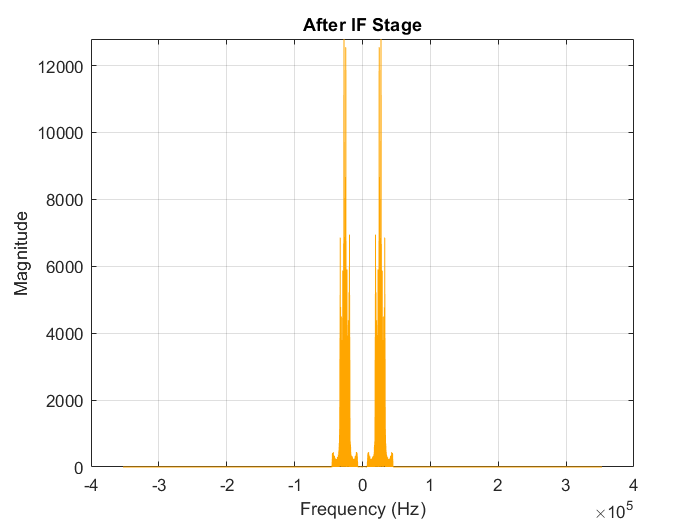

A_stop1 = 60;
F_pass1 = IF - 0.5*(k_IF + BW_Of_chosen_Signal);
F_pass2 = IF + 0.5*(k_IF + BW_Of_chosen_Signal);
F_stop1 = IF - k_IF;
F_stop2 = IF + k_IF;
A_stop2 = 60;
A_pass = 1;
IF_Filter = fdesign.bandpass(F_stop1, F_pass1, F_pass2, F_stop2, A_stop1, A_pass, A_stop2, (x*Fs));
IF_Filter = design(IF_Filter, 'kaiserwin');
[b, a] = tf(IF_Filter);
IF_Signal = filtfilt(b, a, Mixer_Output_Signal);
figure;
IF_SIGNAL = fftshift(fft(IF_Signal));
Frequency_vector = (-length(IF_SIGNAL)/2:1:length(IF_SIGNAL)/2-1)';
plot(Frequency_vector*(x*Fs)/length(IF_SIGNAL), abs(IF_SIGNAL), 'Color', [1, 0.65, 0]);
title("After IF Stage");
xlabel("Frequency (Hz)");
ylabel("Magnitude");
ylim([0 max(abs(IF_SIGNAL))]);
grid on;

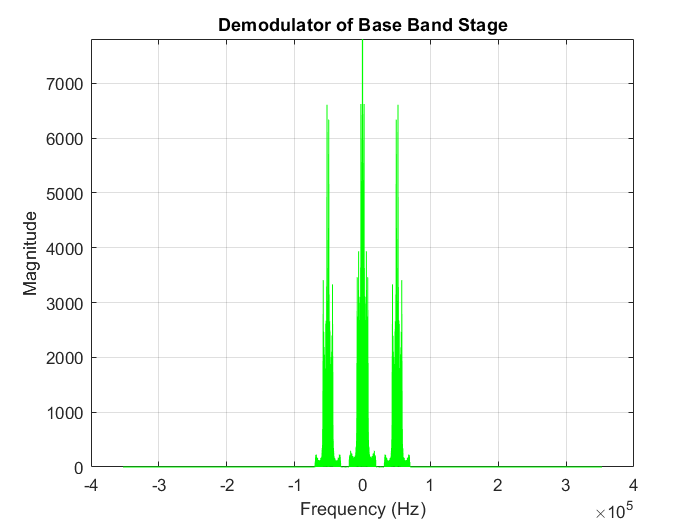


% Update progress bar
progress = 0.85;
waitbar(progress, h, 'Demodulating base band...');

fc = IF;
audio_length = (1:1:length(IF_Signal))';
carrier_signal = cos(2*pi*fc*audio_length*(1/(x*Fs)));
Base_Band_Signal = IF_Signal.*carrier_signal;
figure;
BASE_BAND_SIGNAL = fftshift(fft(Base_Band_Signal));
Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';
plot(Frequency_vector*(x*Fs)/length(BASE_BAND_SIGNAL), abs(BASE_BAND_SIGNAL), 'g');
title("Demodulator of Base Band Stage");
xlabel("Frequency (Hz)");
ylabel("Magnitude");
ylim([0 max(abs(BASE_BAND_SIGNAL))]);
grid on;


% Update progress bar
progress = 0.9;
waitbar(progress, h, 'Filtering base band...');

k2 = 50000 - BW_Of_chosen_Signal;
k_BB = k2 - 100;
disp("k_BB = " + num2str(k_BB) + " Hz");

k_BB = 31623.6093 Hz


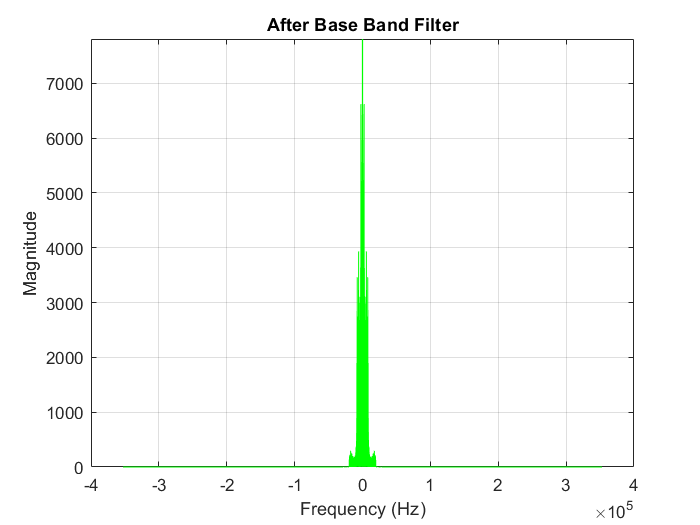

F_pass = 0.5*(k_BB + BW_Of_chosen_Signal);
F_stop = k_BB;
A_stop = 60;
A_pass = 1;
Base_Band_Filter = fdesign.lowpass(F_pass, F_stop, A_pass, A_stop, (x*Fs));
Base_Band_Filter = design(Base_Band_Filter, 'kaiserwin');
[b, a] = tf(Base_Band_Filter);
Base_Band_Signal = filtfilt(b, a, Base_Band_Signal);
figure;
BASE_BAND_SIGNAL = fftshift(fft(Base_Band_Signal));
Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';
plot(Frequency_vector*(x*Fs)/length(BASE_BAND_SIGNAL), abs(BASE_BAND_SIGNAL), 'g');
title("After Base Band Filter");
xlabel("Frequency (Hz)");
ylabel("Magnitude");
ylim([0 max(abs(BASE_BAND_SIGNAL))]);
grid on;

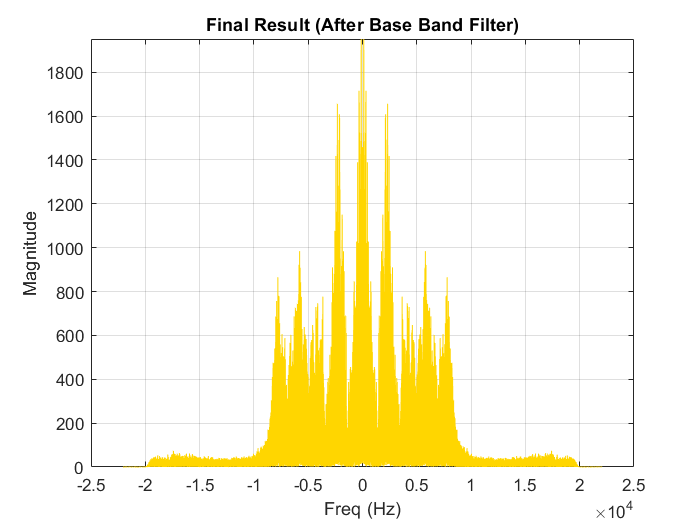


% Update progress bar
progress = 0.95;
waitbar(progress, h, 'Finalizing audio signal...');

Base_Band_Signal = 4*resample(Base_Band_Signal, 1, x);
figure;
BASE_BAND_SIGNAL = fftshift(fft(Base_Band_Signal));
Frequency_vector = (-length(BASE_BAND_SIGNAL)/2:1:length(BASE_BAND_SIGNAL)/2-1)';
plot((Frequency_vector*Fs/length(BASE_BAND_SIGNAL)), abs(BASE_BAND_SIGNAL), 'Color', [1, 0.84, 0]);
title("Final Result (After Base Band Filter)");
xlabel("Freq (Hz)");
ylabel("Magnitude");
ylim([0 max(abs(BASE_BAND_SIGNAL))]);
grid on;

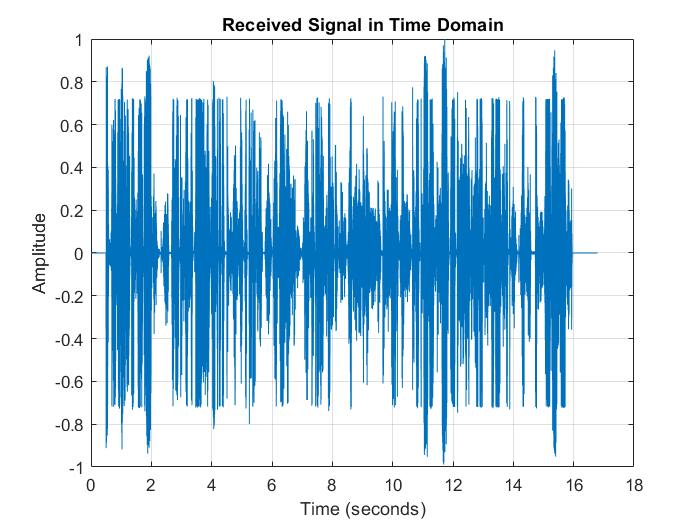

figure;
sound(Base_Band_Signal, Fs);

% Update progress bar
progress = 0.97;
waitbar(progress, h, 'Normalizing and plotting final signal...');

Base_Band_Signal = Base_Band_Signal / max(abs(Base_Band_Signal));
nSamples = length(Base_Band_Signal);
t = (0:nSamples-1) / Fs;
figure;
plot(t, Base_Band_Signal);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Received Signal in Time Domain');
ylim([-max(abs(Base_Band_Signal)) max(abs(Base_Band_Signal))]);
grid on;


% Update progress bar
progress = 0.99;
waitbar(progress, h, 'Saving audio output...');

errors = ["Removed_RF for " + transmitter_Audios(choose_channel), "0.1 KHz Offset for " + transmitter_Audios(choose_channel), "1 KHz Offset for "+ transmitter_Audios(choose_channel)];
receiver = ["received_BBCArabic2.wav", "received_FM9090.wav", "received_QuranPalestine.wav", "received_RussianVoice.wav", "received_SkyNewsArabia.wav"];
if test == 1 || test == 2 || test == 3
    audiowrite(errors{test}, Base_Band_Signal, Fs);
else
    audiowrite(receiver{choose_channel}, Base_Band_Signal, Fs);
end

% Update progress bar
progress = 1.0;
waitbar(progress, h, 'Processing complete!');
pause(1);
close(h);

% Close all figures except the bandwidth table
all_figs = findobj('Type', 'figure');
for fig = all_figs'
    if fig ~= bandwidth_fig
        close(fig);
    end
end